# scenario1

clear;
clc;

N=35 %length

N = 35

x_0=2; %prior mean
P_0=8; %prior covariance

P=zeros(1,N);

Q=1.5; %motion noise covariance
R=3; %measurement noise covariance

A=1;% xk=A*x_{k-1}+q
H=1;% Yk=H*xk+r


## part1

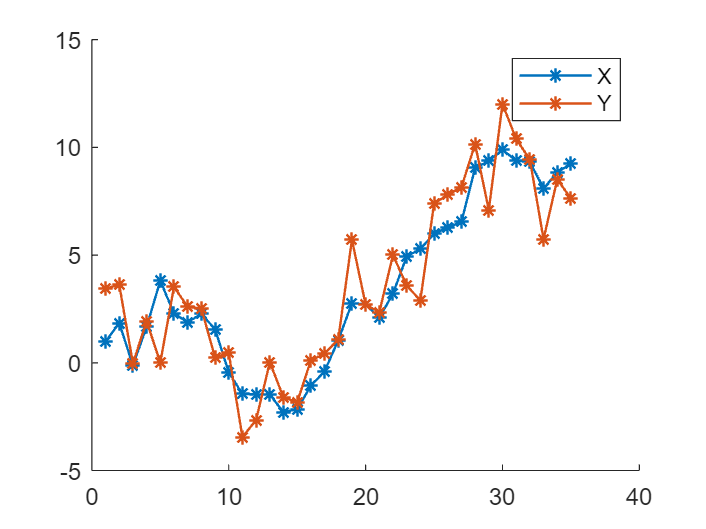

x0 = mvnrnd(x_0,P_0)';%generate only x0, later ones use the equation to build
n=size(x_0,1);
X=zeros(n,N);
Y=zeros(n,N);
X(:,1)=x0;
for i=1:N-1
    X(:,i+1)=A*X(:,i)+mvnrnd(zeros(n,1),Q,1)';
    Y(:,i) = H*X(:,i)+mvnrnd(zeros(n,1),R,1)';
end
Y(:,N) = H*X(:,N)+mvnrnd(zeros(n,1),R,1)';

figure(1)
hold on;
len=1:1:N;

plot(len,X,'-*', 'LineWidth',1);
plot(len,Y,'-*', 'LineWidth',1);
legend('X','Y');

## part2

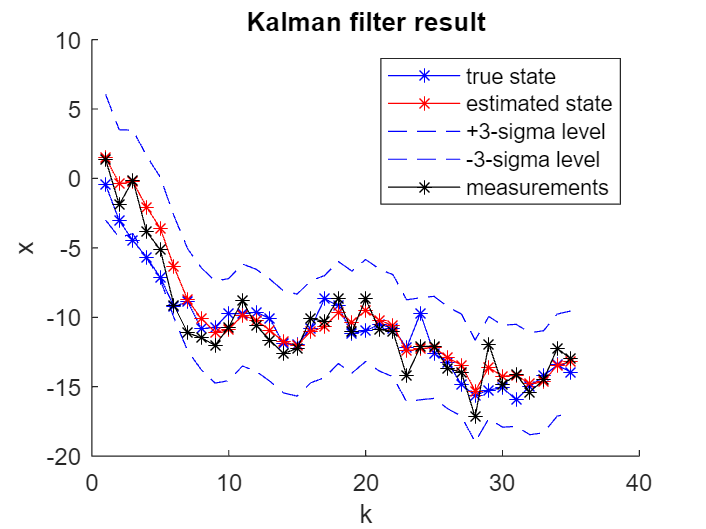

clear;
N = 35; % length
x_0 = 2; % prior mean
P_0 = 8; % prior covariance

P = zeros(1,N);

Q = 1.5; % motion noise covariance
R = 3; % measurement noise covariance

A = 1; % xk = A*x_{k-1} + q
H = 1; % Yk = H*xk + r

% Generate the true state sequence
X = genLinearStateSequence(x_0, P_0, A, Q, N);

% Generate the measurement sequence
Y = genLinearMeasurementSequence(X, H, R);

% Filter the measurement sequence using the Kalman filter
[x_hat, P_hat] = kalmanFilter(Y, x_0, P_0, A, Q, H, R);

% Plot the sequence of estimates together with the +/-3sigma level, true states, and measurements
figure(2); clf; hold on;
plot(1:N, X(2:end), '-*b');
plot(1:N, x_hat, '-*r');
plot(1:N, x_hat + 3*sqrt(squeeze(P_hat))', '--b');
plot(1:N, x_hat - 3*sqrt(squeeze(P_hat))', '--b');
plot(1:N, Y, '-*k');
title('Kalman filter result');
xlabel('k');
ylabel('x');
legend('true state', 'estimated state', '+3-sigma level', '-3-sigma level', 'measurements');

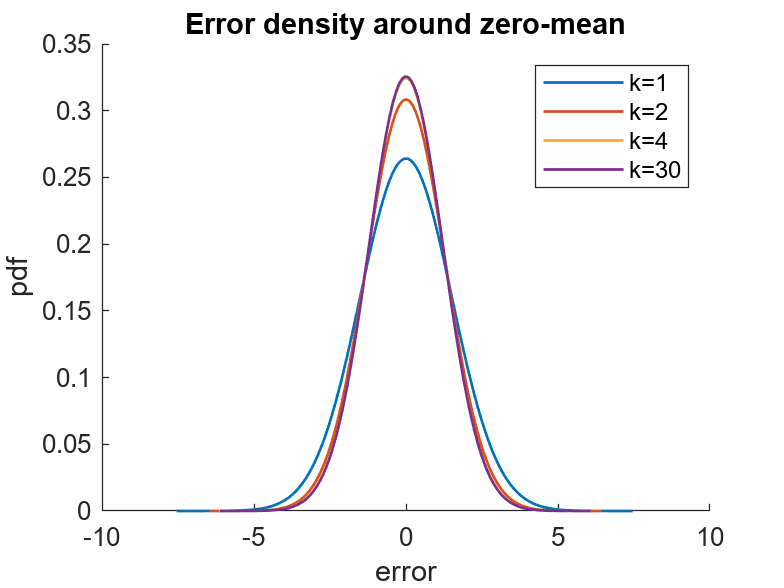


% Plot the error density around zero-mean for time instances k = [1; 2; 4; 30]
k = [1; 2; 4; 30];
figure(3); clf; hold on;
for i = 1:length(k)
%     error = X(k(i)+1) - x_hat(k(i));
    error_sigma = sqrt(squeeze(P_hat(k(i))));
    error_range = [-5*error_sigma:0.1:5*error_sigma];
    error_pdf = normpdf(error_range, 0, error_sigma);
    plot(error_range, error_pdf, 'LineWidth', 1);
end
title('Error density around zero-mean');
xlabel('error');
ylabel('pdf');
legend('k=1', 'k=2', 'k=4', 'k=30');

## part3

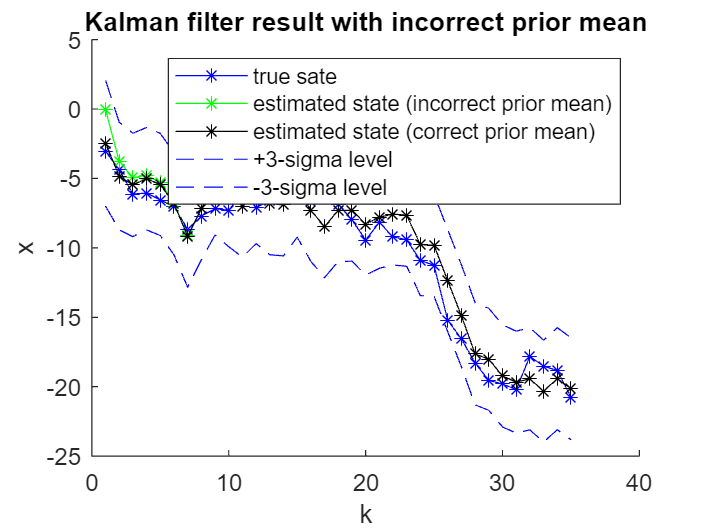

clear;
N = 35; % length
P_0 = 8; % prior covariance

P = zeros(1,N);

Q = 1.5; % motion noise covariance
R = 3; % measurement noise covariance

A = 1; % xk = A*x_{k-1} + q
H = 1; % Yk = H*xk + r

% Generate the true state sequence
X = genLinearStateSequence(2, P_0, A, Q, N);

% Generate the measurement sequence
Y = genLinearMeasurementSequence(X, H, R);

% Filter the measurement sequence using the Kalman filter
[x_hat_incorrect, P_hat_incorrect] = kalmanFilter(Y, 12, P_0, A, Q, H, R);

% Run the Kalman filter again with the correct prior mean

[x_hat_correct, P_hat_correct] = kalmanFilter(Y, 2, P_0, A, Q, H, R);

% Plot the sequence of estimates together with the +/-3sigma level, true states, and measurements
figure(4); clf; hold on;
plot(1:N, X(2:end), '-*b');
plot(1:N, x_hat_incorrect, '-*g');
plot(1:N, x_hat_correct, '-*k');
plot(1:N, x_hat_correct + 3*sqrt(squeeze(P_hat_correct))', '--b');
plot(1:N, x_hat_correct - 3*sqrt(squeeze(P_hat_correct))', '--b');
% plot(1:N, Y, '-*k');
title('Kalman filter result with incorrect prior mean');
xlabel('k');
ylabel('x');
legend('true sate','estimated state (incorrect prior mean)', 'estimated state (correct prior mean)', '+3-sigma level', '-3-sigma level');

## part 4

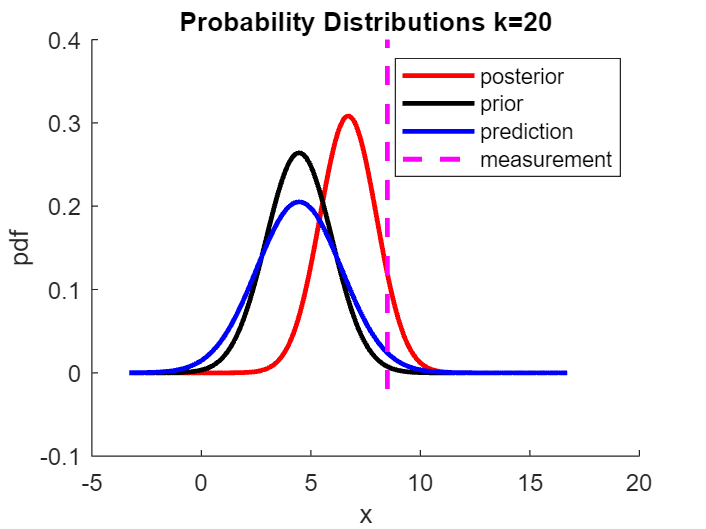

clear;
N = 35; % length
x_0 = 2; % prior mean
P_0 = 8; % prior covariance

P = zeros(1,N);

Q = 1.5; % motion noise covariance
R = 3; % measurement noise covariance

A = 1; % xk = A*x_{k-1} + q
H = 1; % Yk = H*xk + r

% Generate the true state sequence
X = genLinearStateSequence(x_0, P_0, A, Q, N);

% Generate the measurement sequence
Y = genLinearMeasurementSequence(X, H, R);

% Filter the measurement sequence using the Kalman filter
[x_hat, P_hat] = kalmanFilter(Y, x_0, P_0, A, Q, H, R);

k = 20; 
x_range = [x_hat(:,k)-10:0.1:x_hat(:,k)+10];
figure(5); clf; hold on;

% xk_given_y1_k (posterior)
plot(x_range, normpdf(x_range, x_hat(k), sqrt(squeeze(P_hat(k)))), '-r', 'LineWidth', 2);
% xk_1_given_y1_k_1 (prior)
plot(x_range, normpdf(x_range, x_hat(k-1), sqrt(squeeze(P_hat(k-1)))), '-k', 'LineWidth', 2);
% xk_given_y1_k_1(prediction)
[xpre,Ppre]=linearPrediction(x_hat(:,k-1),P_hat(:,:,k-1),A,Q);  
plot(x_range, normpdf(x_range, xpre, sqrt(Ppre)),'-b', 'LineWidth', 2);
% yk
x_coords = [Y(k), Y(k)];
y_coords = [-0.02, 0.4];
plot(x_coords,y_coords,'--m', 'LineWidth', 2)

title('Probability Distributions k=20');
xlabel('x');
ylabel('pdf');
% legend('p(x_{k}\mid y_{1:k})', 'p(x_{k-1}\mid y_{1:k-1})', 'p(x_{k}\mid y_{1:k-1})','y_k');
legend('posterior','prior','prediction','measurement')

function Y = genLinearMeasurementSequence(X, H, R)
%GENLINEARMEASUREMENTSEQUENCE generates a sequence of observations of the state 
% sequence X using a linear measurement model. Measurement noise is assumed to be 
% zero mean and Gaussian.
%
%Input:
%   X           [n x N+1] State vector sequence. The k:th state vector is X(:,k+1)
%   H           [m x n] Measurement matrix
%   R           [m x m] Measurement noise covariance
%
%Output:
%   Y           [m x N] Measurement sequence
%

% your code here
N=size(X,2)-1;
m=size(R,1);
for i=2:N+1
    Y(:,i-1)=H*X(:,i)+mvnrnd(zeros(m,1),R,1)';
end

end
%exprience
%The index of Y should be 1 less then X since there is a x0 in X that do
%not generate an observation Y


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function X = genLinearStateSequence(x_0, P_0, A, Q, N)
%GENLINEARSTATESEQUENCE generates an N-long sequence of states using a 
%    Gaussian prior and a linear Gaussian process model
%
%Input:
%   x_0         [n x 1] Prior mean
%   P_0         [n x n] Prior covariance
%   A           [n x n] State transition matrix
%   Q           [n x n] Process noise covariance
%   N           [1 x 1] Number of states to generate
%
%Output:
%   X           [n x N+1] State vector sequence
%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Your code here
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
x0 = mvnrnd(x_0,P_0)';%generate only x0, later ones use the equation to build
n=size(x_0,1);
X=zeros(n,N+1);
X(:,1)=x0;
for i=1:N
    X(:,i+1)=A*X(:,i)+mvnrnd(zeros(n,1),Q,1)';
end
end

%Error experience:
%The mvnrnd function generate a row vector, the X series is boring that it
%asks to save the value x in column vector.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [x, P] = linearPrediction(x, P, A, Q)
%LINEARPREDICTION calculates mean and covariance of predicted state
%   density using a liear Gaussian model.
%
%Input:
%   x           [n x 1] Prior mean
%   P           [n x n] Prior covariance
%   A           [n x n] State transition matrix
%   Q           [n x n] Process noise covariance
%
%Output:
%   x           [n x 1] predicted state mean
%   P           [n x n] predicted state covariance
%

% Your code here
n=size(x,1);
% pre=mvnrnd(x,P,1)';
% x=A*pre+mvnrnd(zeros(n,1),Q,1)';
x=A*x;
P=A*P*A'+Q;
end

% exprience
% x should just use A*x

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [x, P] = linearUpdate(x, P, y, H, R)
%LINEARPREDICTION calculates mean and covariance of predicted state
%   density using a linear Gaussian model.
%
%Input:
%   x           [n x 1] Prior mean
%   P           [n x n] Prior covariance
%   y           [m x 1] Measurement
%   H           [m x n] Measurement model matrix
%   R           [m x m] Measurement noise covariance
%
%Output:
%   x           [n x 1] updated state mean
%   P           [n x n] updated state covariance
%

% Your code here
innovation = y - H*x;
S = H*P*H' + R;
K = P*H'/S;
x = x + K*innovation;
P = P - K*S*K';
end

%video 4.1.3

%%%%%%%%%%%%%%%%%%%%%%%
function [X, P] = kalmanFilter(Y, x_0, P_0, A, Q, H, R)
%KALMANFILTER Filters measurements sequence Y using a Kalman filter. 
%
%Input:
%   Y           [m x N] Measurement sequence
%   x_0         [n x 1] Prior mean
%   P_0         [n x n] Prior covariance
%   A           [n x n] State transition matrix
%   Q           [n x n] Process noise covariance
%   H           [m x n] Measurement model matrix
%   R           [m x m] Measurement noise covariance
%
%Output:
%   x           [n x N] Estimated state vector sequence
%   P           [n x n x N] Filter error convariance
%

%% Parameters
N = size(Y,2);

n = length(x_0);
m = size(Y,1);

%% Data allocation
x = zeros(n,N);
P = zeros(n,n,N);

% Initialize state estimate and covariance
tempX(:,1) = x_0;
tempP(:,:,1) = P_0;

for i=1:N

xt = tempX(:,i);

% xk = A*xt + mvnrnd(zeros(n,1),Q,1)';

%Error experience:
%Forget to update P at linear update step

xk = A*xt;
tempPt = A*tempP(:,:,i)*A'+Q;


S = H*tempPt*H' + R;
innovation = Y(:,i) - H*xk;
K = tempPt*H'/S;
tempX(:,i+1) = xk + K*innovation;
tempP(:,:,i+1) = tempPt - K*S*K';
end
X=tempX(:,2:N+1);
P=tempP(:,:,2:N+1);

end





